clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

## 参数设置

# MLA

lambda = 647e-6;    % 波长
N = 90;           % 微透镜单元采样点数
rla = -0.94;            % 透镜1的曲率半径
d = 0.3;              % 透镜单元边长
t = 1;            % 透镜厚度
beamStd=1;       %初始高斯光束腰斑直径
material={"F_SILICA"};
MLA1=Lens([rla,inf],t,d,material,lambda);
MLA2=Lens([inf,-rla],t,d,material,lambda);
num=floor(beamStd/d*5);            %数量
if num==0
    num=1;
end
rate=(d/N);           %采样率（global）
area1 = [rate,num*d];           % 光场的面积
area2=30;
area3=5;
area2=findClosestDivisible(area2,rate);
area2=[rate*1,area2];
peak=0;
SD=0;

color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)
distance1 = 1.359;   % 投影距离
%distance2 = 298.3;   % 投影距离
distance2=150;
distance3=150;
%distance4 = 2.795;
distance4 = linspace(0,4,5000)';

# Fourier Lens

rfl1 = inf;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = 77.3;
dfl = 50.8;              % 傅里叶透镜直径
Dfl = area2(2);              %采样区域
tfl = 7.3;            % 傅里叶透镜厚度

material_fl={'N-BK7'};

FL=Lens([rfl1,rfl2],tfl,dfl,material_fl,lambda);
beam=GaussianBeam(1,beamStd,lambda);
beams=GaussianBeam.defocused(beam,10,N*num,rate);
beams=beams(721,:);
f_FL=((FL.n_curwl-1).*(1/rfl2-1/rfl1+(FL.n_curwl-1)*tfl/FL.n_curwl/rfl1/rfl2))^-1;
d_ex=lambda*f_FL/d;

# Ex-MLA

rla_ex = -1.6;            % 透镜1的曲率半径
d_ex = 0.15;              % 透镜单元边长
t_ex=1;
material_ex={"F_SILICA"};
MLA3=Lens([rla_ex inf],t_ex,d_ex,material_ex,lambda);
%aperture=drawCircle(23/2/rate,0,0,round(area3/rate),round(area3/rate));

# Diffuser

diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square',0);
Lens.lensArrayThickFcn(MLA2,N,num,'square',0);
Lens.lensArrayThickFcn(MLA3,ceil(d_ex/rate),ceil(area2(2)/d_ex),'square',0,d_ex-0.001)
MLA1.thick_edge=MLA1.thick_edge(N/2+1,:,:);
MLA1.thick_air=MLA1.thick_air(N/2+1,:,:);
MLA2.thick_edge=MLA2.thick_edge(N/2+1,:,:);
MLA2.thick_air=MLA2.thick_air(N/2+1,:,:);
MLA3.thick_edge=MLA3.thick_edge(ceil(d_ex/rate/2)+1,:,:);
MLA3.thick_air=MLA3.thick_air(ceil(d_ex/rate/2)+1,:,:);

## 生成傅里叶透镜厚度函数

Lens.lensThickFcn(FL,Dfl,round(area2/rate));

if size(MLA2.thick_edge,1)>size(FL.thick_edge,1)
    siz_FL=size(FL.thick_edge,1);
    siz_MLA2=size(MLA2.thick_edge,1);
    MLA2.thick_edge=MLA2.thick_edge(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
    MLA2.thick_air=MLA2.thick_air(round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,round((siz_MLA2-siz_FL)/2):round((siz_MLA2-siz_FL)/2)+siz_FL-1,:);
end
Lens.lensSingle(MLA1)
Lens.lensSingle(FL);
Lens.lensSingle(MLA2);
Lens.lensSingle(MLA3);
beams=single(beams);
N= single(N);
num= single(num);
rate= single(rate);
lambda= single(lambda);
distance1= single(distance1);
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
if ~canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(FL)
    Lens.lensGPUArray(MLA2);
    beams=gpuArray(beams);
    N=gpuArray(N);
    num=gpuArray(num);
    rate=gpuArray(rate);
    lambda=gpuArray(lambda);
    distance1=gpuArray(distance1);
    distance2=gpuArray(distance2);
    distance3=gpuArray(distance3);
    area1=gpuArray(area1);
    area2=gpuArray(area2);
end
I=zeros(1,9000);

## 光场变换

历时 4.592987 秒。
历时 9.276177 秒。
历时 14.411919 秒。
历时 19.210948 秒。
历时 24.012272 秒。


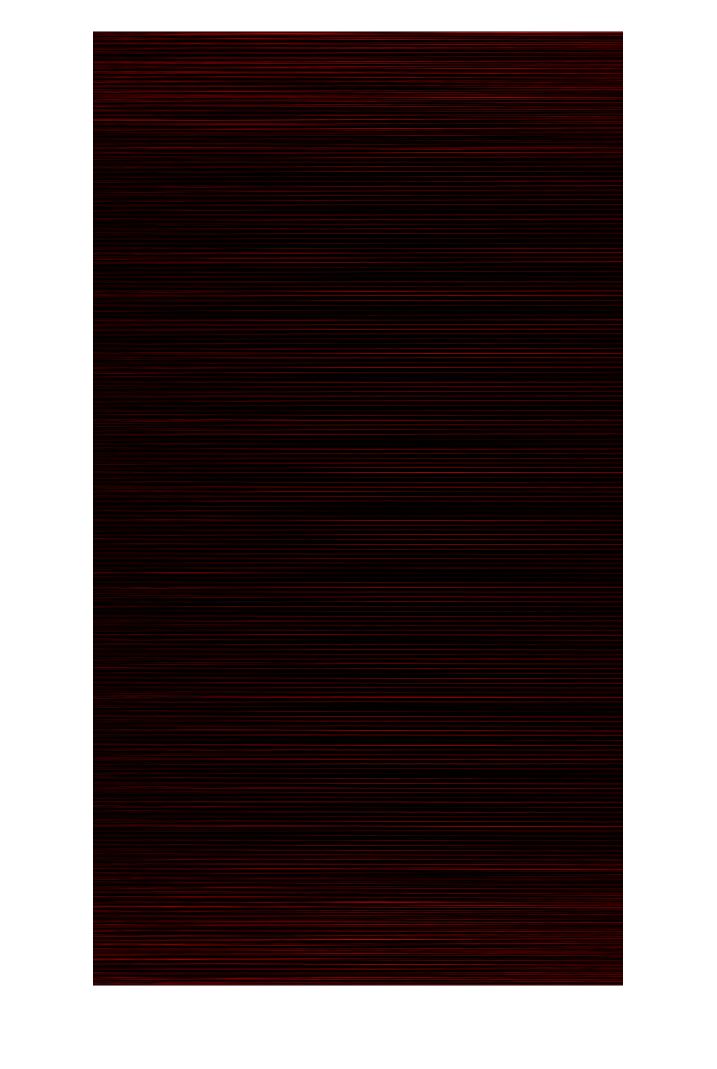

历时 28.813320 秒。


tic
for ii=1:100
    %叠加随机相位
    F = transform(beams, area1, lambda, 20, [rate, rate]);
    if mod(ii,2)
        [phase1,phase2]=Diffuser.generateDiffuser(diffuser,rate,[1,N*num]);
        F=F.*phase1;
    else
        F=F.*phase2;
    end
    F=transform(F,area1,lambda,10,[rate, rate]);
    afterLens=ASMinLens(F,MLA1,lambda,area1);
    F = transform(afterLens, area1, lambda, distance1, [rate, rate]);
    afterLens = ASMinLens(F,MLA2,lambda,area1);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, area2, lambda, distance3, [rate, rate]);
    afterLens = ASMinLens(F,MLA3,lambda,area2);
    F = transform(afterLens, area2, lambda, distance4, [rate, rate]);

    I = I+abs(F).^2;
    Inorm=(I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all'));
    Inorm=gather(Inorm);
    %plot(Inorm)
    imshow(uint16(Inorm'*65536),mymap)
    %plot(Inorm)
    %meanFWHM(ii)=calMeanDia(Inorm,gather(ceil(d_ex/rate)*0.5),0.5)*rate;
    %meanFWHM(ii)=meanFWHM(ii)*1e3;
    %disp(['平均FWHM=' num2str(meanFWHM(ii)) 'μm'])
    
    %plot(Inorm(:,3073))
    %hist=imhist(Inorm);
    %[~,peak(end+1)]=max(hist);
    %SD(end+1)=std(Inorm,0,'all');
    %subplot(2,2,3)
    %plot(peak)
    %subplot(2,2,4)
    %plot(SD)
    toc
    drawnow
end

%imshow(II)
%plot(meanFWHM)

